**Problema 1 **

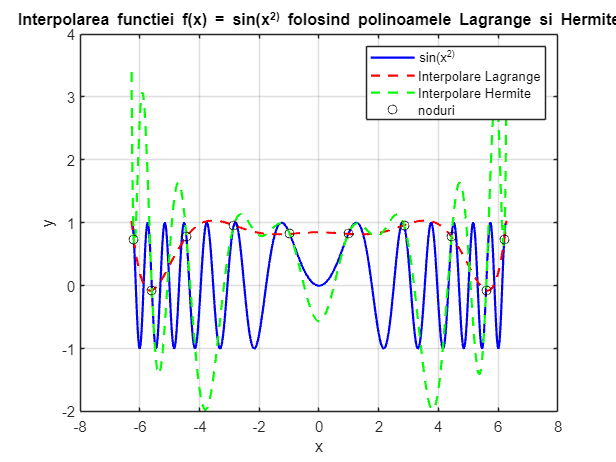

a = -2*pi;
b = 2*pi;
n = 9;

% generare noduri Cebisev de speta I
k = 0:n;
xk = 0.5*(a + b) + 0.5*(b - a)*cos((2*k+1)/(2*(n+1))*pi);

f = @(x) sin(x.^2);
fderiv = @(x) 2*x.*cos(x.^2);

yk = f(xk);
fyk = fderiv(xk);

xi = linspace(a, b, 1000);
true_values = f(xi);

% interpolare lagrange
yi_lagrange = lagrange(xk, yk, xi);

% interpolare hermite
yi_hermite = arrayfun(@(x) hermite(xk, yk, fyk, x), xi);

figure;
plot(xi, f(xi), 'b', 'LineWidth', 1.5, 'DisplayName', 'sin(x^2)');
hold on;
plot(xi, yi_lagrange, 'r--', 'LineWidth', 1.5, 'DisplayName', 'Interpolare Lagrange');
plot(xi, yi_hermite, 'g--', 'LineWidth', 1.5, 'DisplayName', 'Interpolare Hermite');
scatter(xk, yk, 'ko', 'DisplayName', 'noduri');
legend('show');
xlabel('x');
ylabel('y');
title('Interpolarea functiei f(x) = sin(x^2) folosind polinoamele Lagrange si Hermite');
grid on;

t = pi/5;
lagrange_at_t = lagrange(xk, yk, t);
hermite_at_t = hermite(xk, yk, fyk, t);

fprintf('Approximation of sin((pi/5)^2) using Lagrange interpolation: %f\n', lagrange_at_t);

Approximation of sin((pi/5)^2) using Lagrange interpolation: 0.835273


fprintf('Approximation of sin((pi/5)^2) using Hermite interpolation: %f\n', hermite_at_t);

Approximation of sin((pi/5)^2) using Hermite interpolation: 0.245390


error_lagrange = abs(true_values - yi_lagrange);
error_hermite = abs(true_values - yi_hermite);

max_error_lagrange = max(error_lagrange);
max_error_hermite = max(error_hermite);

mean_squared_error_lagrange = sqrt(mean(error_lagrange.^2));
mean_squared_error_hermite = sqrt(mean(error_hermite.^2));

fprintf('Maximum absolute error for Lagrange interpolation: %f\n', max_error_lagrange);

Maximum absolute error for Lagrange interpolation: 2.024515


fprintf('Maximum absolute error for Hermite interpolation: %f\n', max_error_hermite);

Maximum absolute error for Hermite interpolation: 3.812975



fprintf('Mean squared error for Lagrange interpolation: %f\n', mean_squared_error_lagrange);

Mean squared error for Lagrange interpolation: 0.952350


fprintf('Mean squared error for Hermite interpolation: %f\n', mean_squared_error_hermite);

Mean squared error for Hermite interpolation: 1.282872


**Problema 2, subpunctul a)**

f = @(x) (x.^2).*sin(x);
n = 12;

% generare noduri echidistante
x = linspace(-2*pi, 2*pi, n);
y = f(x);

% spline deBoor
type = 3; 
c = cubicspline(x, y, type);

disp('Spline Coefficients:');

Spline Coefficients:


disp(c);

   4.057055291259523 -23.060620016266252  47.387404221951407   0.000000000000010
   4.057055291259489  -9.156312636380621  -0.006629313086623  24.039482430497014
   2.233612319491684   2.664898363742848 -15.632175635104289  12.082265022586498
  -2.129140103108448   5.335919891516142  -6.628405962334508  -2.298007341266390
  -0.714865188216575  -0.345388121715175   2.784394895866377  -2.906522794437223
   1.154711082761484  -0.659569428113126   1.062303665479004  -0.176393751780771
  -0.714865188216575   1.162048203027275   1.062303665479004   0.176393751780771
  -2.129140103108448  -2.903595925556536   2.784394895866377   2.906522794437223
   2.233612319491681  -5.216571110609295  -6.628405962334508   2.298007341266390
   4.057055291259490   4.521543509752112 -15.632175635104291 -12.082265022586498
   4.057055291259513  18.425850889637701  -0.006629313086621 -24.039482430497014



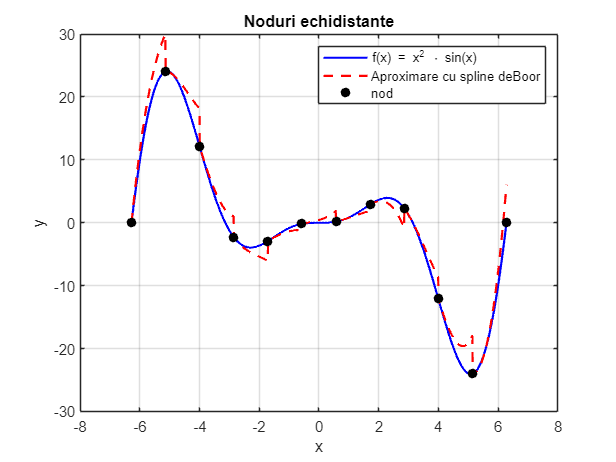

xx = linspace(a, b, 1000);
yy = f(xx);
yy_spline = zeros(size(xx));

for i = 1:length(x)-1
    idx = xx >= x(i) & xx <= x(i+1);
    dx = xx(idx) - x(i);
    yy_spline(idx) = c(i,1)*dx.^3 + c(i,2)*dx.^2 + c(i,3)*dx + c(i,4);
end

figure;
plot(xx, yy, 'b-', 'LineWidth', 1.5); hold on;
plot(xx, yy_spline, 'r--', 'LineWidth', 1.5);
plot(x, y, 'ko', 'MarkerFaceColor', 'k');
legend('f(x) = x^2 \cdot sin(x)', 'Aproximare cu spline deBoor', 'nod');
xlabel('x');
ylabel('y');
title('Noduri echidistante');
grid on;

f = @(x) (x.^2).*sin(x);

a = -2*pi;
b = 2*pi;
n = 12;

% generare noduri cebisev de speta a doua
k = 0:n-1;
x_chebyshev = cos((2*k + 1) * pi / (2*n));  
x = 0.5 * (a + b) + 0.5 * (b - a) * x_chebyshev; 

disp('Chebyshev nodes:');

Chebyshev nodes:


disp(x);

   6.229431785862627   5.804906304278862   4.984786051119735   3.824960866325243   2.404470919537385   0.820120253159127  -0.820120253159127  -2.404470919537383  -3.824960866325243  -4.984786051119735  -5.804906304278862  -6.229431785862627



y = f(x);
c = cubicspline(x, y, 3);

disp('Spline Coefficients:');

Spline Coefficients:


disp(c);

 -22.598299070349412  10.972378707060539  26.963455872348813   2.084945099835246
  16.006153097491396 -26.748051639108166  32.206856536549751  15.509081957393695
   6.448458333983851 -10.146905230671829  -0.900686996412752  23.931911862828855
   0.039599586990196   4.593212098631815 -15.763529043128969   9.237711705597139
  -1.891360607515141   3.014967698502522  -2.634402106473557  -3.886077627975246
   1.168458745841018  -0.958276682445130   2.171499011497831  -0.491821835358554
  -1.891360607515144  -0.018389259624328   2.171499011497836   0.491821835358555
   0.039599586990194  -4.649462913848335  -2.634402106473584   3.886077627975245
   6.448458333983851   2.667820851819423 -15.763529043128967  -9.237711705597139
  16.006153097491389  13.621081308689787  -0.900686996412754 -23.931911862828855
 -22.598299070349412  -1.378824911246479  32.206856536549751 -15.509081957393695



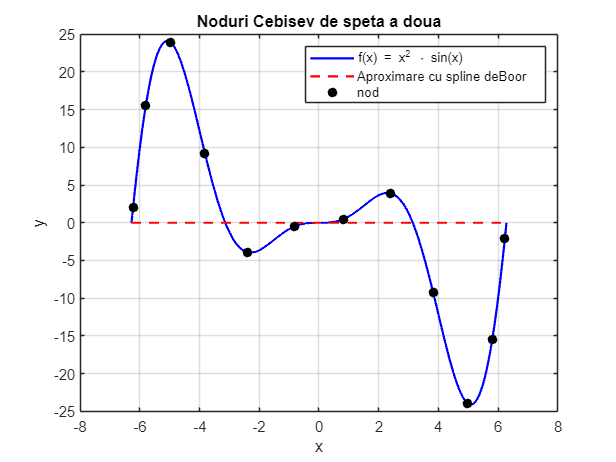

xx = linspace(a, b, 1000);
yy = f(xx);
yy_spline = zeros(size(xx));

% loop peste fiecare interval definit de nodurile x
for i = 1:length(x)-1
    % gasim indicele xx care este intervalul [x(i), x(i+1))
    idx = find(xx >= x(i) & xx < x(i+1));
    
    % daca ultimul interval si idx nu au valori, includem si x(i+1)
    if isempty(idx) && i == length(x)-1
        idx = find(xx >= x(i) & xx <= x(i+1));
    end

    % daca idx are valori, calculam dx si evaluam spline-ul pe intervalul acesta
    if ~isempty(idx)
        dx = xx(idx) - x(i); % calculeaza distanta de la x la x(i)
        yy_spline(idx) = c(i,1)*dx.^3 + c(i,2)*dx.^2 + c(i,3)*dx + c(i,4); % evaluare spline
    end
end

% includem si intervalul [x(end-1), x(end)]
idx = find(xx >= x(end-1) & xx <= x(end));
dx = xx(idx) - x(end-1);
if ~isempty(idx)
    yy_spline(idx) = c(end,1)*dx.^3 + c(end,2)*dx.^2 + c(end,3)*dx + c(end,4);
end

figure;
plot(xx, yy, 'b-', 'LineWidth', 1.5); hold on;
plot(xx, yy_spline, 'r--', 'LineWidth', 1.5);
plot(x, y, 'ko', 'MarkerFaceColor', 'k');
legend('f(x) = x^2 \cdot sin(x)', 'Aproximare cu spline deBoor', 'nod');
xlabel('x');
ylabel('y');
title('Noduri Cebisev de speta a doua');
grid on;

**Problema 2, subpunctul b)**

f = @(x) x.^2 .* sin(x);

a = -2*pi;
b = 2*pi;
n = 11;

x_nodes = linspace(a, b, n);
y_nodes = f(x_nodes);

grad = n - 1;
A = zeros(n, grad + 1);
for i = 0:grad
    A(:, i + 1) = x_nodes'.^i;
end

coeffs = (A' * A) \ (A' * y_nodes');

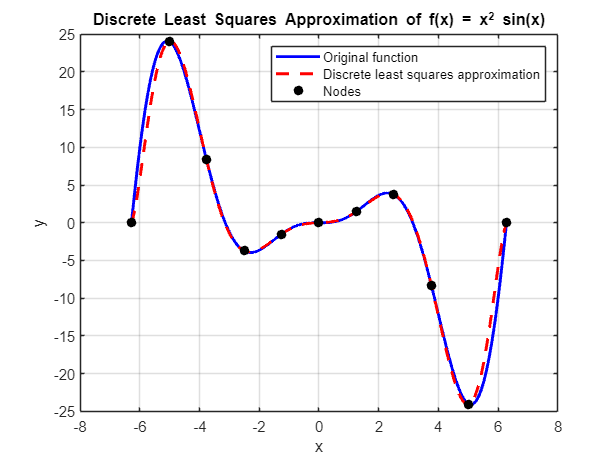

p = @(x) polyval(flip(coeffs'), x);

x_fine = linspace(a, b, 1000);

y_fine = f(x_fine);
y_approx = p(x_fine);

figure;
plot(x_fine, y_fine, 'b', 'LineWidth', 2);
hold on;
plot(x_fine, y_approx, 'r--', 'LineWidth', 2);
plot(x_nodes, y_nodes, 'ko', 'MarkerFaceColor', 'k');
legend('f(x) = x^2 \cdot sin(x)', 'MCMMP', 'nod');
xlabel('x');
ylabel('y');
title('Aproximare MCMMP f(x) = x^2 sin(x)');
grid on;
hold off;